funHandle = @(x)15*sin(2*x)^2 + (x-2)^2;

popsize = 100;

init_guess = 10;

dev = 10;

init_pop = init_guess + dev*rand(popsize,1);

MaxGen = 10000;

options = optimoptions('ga', ...
   'PopulationSize',popsize,'EliteCount', 20, 'MaxGenerations',MaxGen,...
  'CrossoverFraction',.6, 'MutationFcn', ... 
{@mutationgaussian, .05, 10}) %'ConstraintTolerance', 1e-4, 'InitialPopulationMatrix',init_pop, 

options =   ga options:

   Set properties:
               CrossoverFraction: 0.6000
                      EliteCount: 20
                  MaxGenerations: 10000
                     MutationFcn: {@mutationgaussian  [0.0500]  [10]}
                  PopulationSize: 100

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
                         Display: 'final'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
    NonlinearConstraint

%THIS SETUP CONSISTANTLY PRODUCED GOOD RESULTS WHEN THE INITIAL GUESS WAS GOOD
% popsize = 100;
% 
% init_guess = 1.5;
% 
% init_pop = init_guess + .003*rand(popsize,1);
% 
% MaxGen = 1000000;
% 
% options = optimoptions('ga', 'InitialPopulationMatrix',init_pop, ...
%    'PopulationSize',popsize,'EliteCount', 4, 'MaxGenerations',MaxGen,...
%   'CrossoverFraction',.5, 'ConstraintTolerance', 1e-6,'MutationFcn', ... 
% {@mutationgaussian, .05, 5})

%% THIS ONE WORKED WELL FOR VARIOUS INITIAL CONDITIONS AND I DIDNT INTRODUCE THE NONLINEAR CONSTRAINT
% popsize = 100;
% 
% init_guess = 10;
% 
% dev = 10;
% 
% init_pop = init_guess + dev*rand(popsize,1);
% 
% MaxGen = 10000;
% 
% options = optimoptions('ga', 'InitialPopulationMatrix',init_pop, ...
%    'PopulationSize',popsize,'EliteCount', 4, 'MaxGenerations',MaxGen,...
%   'CrossoverFraction',.6, 'MutationFcn', ... 
% {@mutationgaussian, .05, 5}) %'ConstraintTolerance', 1e-4,

lb = -10;
ub = 10;

[x, fval] = ga(funHandle,1,[],[],[],[],lb,ub,[], options) %,@nlCon

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x = 1.5773

fval = 0.1812


%Check the derivative of the function


[c, ceq] = nlCon(x)


c =

     []



ceq = -0.0615

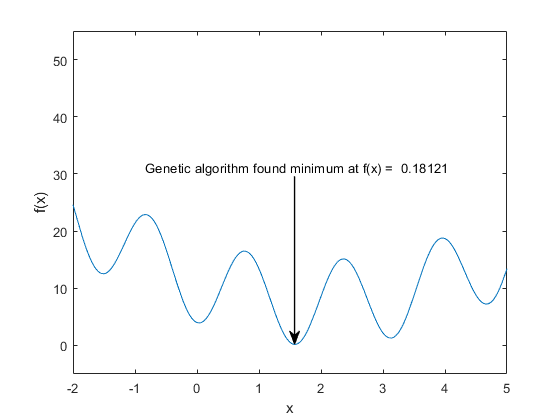

figure
fplot(funHandle, [-2 5])
ylim([-5 55])
xlabel('x')
ylabel('f(x)')

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .4; %Length of Arrow
PhiArr = deg2rad(90);
%Arrow Head
[xh, yh] = ds2nfu(ax,x, fval);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Genetic algorithm found minimum at f(x) =  ' num2str(fval)],'FontSize',10,'Linewidth',1)

function [c, ceq] = nlCon(x)

c = [];
ceq = 60*sin(2*x)*cos(2*x) + 2*(x-2);   % Compute nonlinear equalities at x.

end
